# Machine Learning for Regression: Part 2

*                An application in electricity load forecasting*

**Suggested Prework**

- [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

- [Machine Learning for Regression: Part 1](matlab:open('./machineLearningIntro.mlx'))

## **Can you predict future electricity demand?**

The amount of electricity required to support an electrical grid is also referred to as the ***load*** on the grid, and it varies significantly over a day. Having a forecast of the electrical load is vital to several entities. It helps utility companies plan how much electricity their power plants will need to produce. It also supports energy traders to gain insight into upcoming market dynamics. Below is an example profile of the electrical load on the grid in New York City (left). This script walks you through the steps to predict future demand based on the historical load data for New York City. You will achieve a result similar to the one shown below (right).

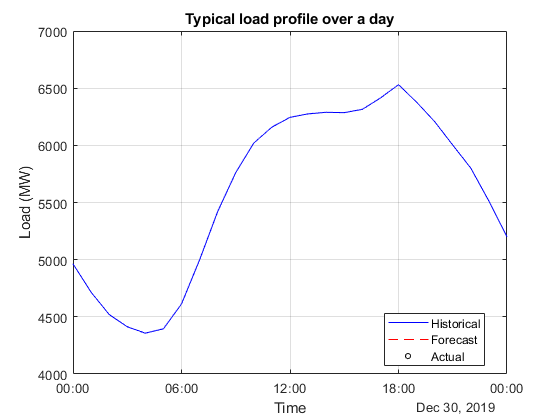   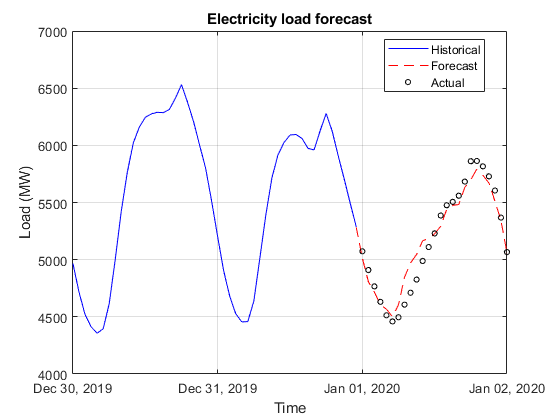

In this script, you will follow the steps of this workflow in MATLAB. The final step for integrating the model in a production environment or a system is optional and not within the scope of this module.

 **For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.**

Use this script in a controls-only mode (default) by using the **Hide code **  button, or view the code by using the **Output inline**    button on the **View** tab of the MATLAB toolstrip.

### 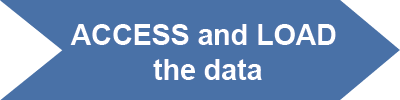

### 1.a. Download the NYISO electricity load data

**NOTE: **This section requires you to download external data from [New York ISO](http://mis.nyiso.com/public/) and take approximately 1-5 minutes (depending on your internet connection). The script `electricityLoadDataML.mlx` included with this module downloads, formats, and saves the data.

***Task:**** Click the ****Open script to load data**** button to open *`electricityLoadDataML.mlx`*. If viewing code in Output inline mode, you can alternatively use* *the ****Run Section**** button in the MATLAB toolstrip, or click the vertical blue-striped bar on the left to run a section. *

*Set the parameters in this script to download electricity data for the start and end dates given below.*

**          Start date: **`2017-May-01`       **         End date:** `2020-Dec-31`

edit electricityLoadDataML.mlx
 


View the contents of `nyiso_cleaned.mat` file. It should contain a `timetable` variable named `nyiso`.

whos('-file','nyiso_cleaned.mat')
 

### 1.b. Bring the data into the MATLAB workspace

The very first step is to access the data and get familiar with it. To do this, load the data from `nyiso_cleaned.mat` and inspect the first few rows.

***Task:**** In the edit field below, use the *[`head`](https://www.mathworks.com/help/matlab/ref/table.head.html)* or *[`display`](https://www.mathworks.com/help/matlab/ref/display.html)* function to preview the contents of the variable *`nyiso`*.*

clearvars;
load nyiso_cleaned.mat nyiso;
 
 

  ***Try***

- *Open the table in a separate window by clicking on the arrow in the top right corner.*

- *Inspect the individual rows and columns.*

 **Reflect**

 This data contains a record electrical load at regular time intervals. When observations are organized by time in this manner, we call it a* time series*.

- How many regions or zones are there? (**Hint:** Regions correspond to individual columns of data.)

- What is the interval between successive observations (rows)?

- (Optional) Note that the data is stored in a MATLAB `timetable`. Follow [this example](https://www.mathworks.com/help/releases/R2021a/matlab/matlab_prog/preprocess-and-explore-bicycle-count-data-using-timetable.html) to learn how to process and operate on a `timetable` in MATLAB.

### 1.c. Visualize the data

Another way to get familiar with the data is to plot and visualize it.

***Task: ****Select a region (zone) from the* *drop-down list below.*

allregions = string(nyiso.Properties.VariableNames);
region = allregions(3);

% Plot the load profile for the selected region.
figure
plot(nyiso.Date,nyiso{:,region},"b")
xlabel("Date")
ylabel("Load (MW)")
title("Raw Data for " + region + " region","Interpreter","none")

  ***Try***

- *Select different regions by using the drop-down list.*

- *Observe the plot for each region. Use the plot tools such as ****Zoom ***   *and**** Pan ***   *that appear in the axes toolbar on the right side above the axes.*

 **Reflect**

- Which region might be the most difficult to model and make reliable forecasts? Why?

- Which region seems to have the highest average load?

### 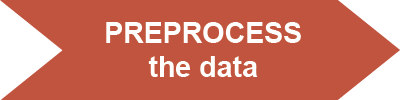

### 2. Extract and retime the load data for NYC region

Some initial cleanup of the data has already been done for you in `electricityLoadDataML.mlx`. This includes aggregating the raw data from multiple monthly CSV files, removing spikes and missing data, and storing in appropriate MATLAB formats.

From an initial exploration of the cleaned data, it is evident that the load profile follows a different pattern for the different regions. The average load level also varies across regions. Because of this difference in behavior, you'll want to model each zone separately. 

***Task: ***Start by extracting the data for New York City zone. After modeling for New York City's electrical load by the end of this script, you can return to this section to repeat the same process for another zone.

% Extract the data for New York City.
allregions = string(nyiso.Properties.VariableNames);
nycData = nyiso(:,allregions(2));

% Change the table column name to be more general.
nycData.Properties.VariableNames = "Load"

***Task: ***Your goal in this module is to make hourly forecasts. Use the function [`retime`](https://www.mathworks.com/help/matlab/ref/timetable.retime.html) to resample the `timetable` variable `nycData` from 5-minute time steps to 1-hour time steps.

nycHourly = retime(nycData,'daily');
nycHourly = timetable2table(nycHourly);
nycHourly(end,:) = []

 **Reflect**

- If you are asked to predict the electricity demand in your region for the next hour, what specific information will you need? In other words, what factors determine the electricity load requirement at any given hour?

### 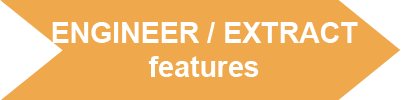

### 3.a. Extract f**eatures to apply regression models for load forecasting**

Recall that a supervised machine learning algorithm attempts to learn the relationship between the inputs (predictors or features) and the output. For load forecasting, the output is the electrical load at a given hour. Time series data do not contain any natural "features" other than the time stamps. This section will engineer a reasonable set of features from the time series to translate this forecasting problem into a supervised machine learning problem.

To predict the load at a given time stamp, it is reasonable to consider the immediately preceding value or a few preceding values as inputs to the model. Additionally, to capture any repeating patterns that occur daily, weekly, or yearly, it is also reasonable to extract the corresponding past values as features. A common way to transform a time series for machine learning is to use a chosen set of past values as ***lag features***. In practice, this means appending a lagged (delayed) version of the original time series as a column of the input variable. Each observation (row) then includes specific measurements from the past as inputs to the model. The choice of lags depends on the domain of the problem.

In electricity load forecasting, the current hour's requirement is influenced heavily by the previous hour. Moreover, the plots from earlier sections indicate a daily and weekly pattern in the load requirement. 

***Task: ****The function *[`lagmatrix`](https://www.mathworks.com/help/releases/R2021a/econ/lagmatrix.html)* is used to extract lag features. Calculate the lags (in number of hours) for the previous hour, the previous day, and the previous week. Enter appropriate lags in the edit fields provided below.*

previousHour = 0;
previousDay = 0;
previousWeek = 0;
 

previousLoads = lagmatrix(nycHourly.Load,[previousHour previousDay previousWeek]);
nycHourly.PreviousLoad = previousLoads(:,1);
nycHourly.PreviousDayLoad = previousLoads(:,2);
nycHourly.PreviousWeekLoad = previousLoads(:,3)

  ***Try***

- *Enter the computed lag numbers in the respective edit fields.*

- *Inspect a few rows of the data to determine if the your computed lags are correct.*

 **Reflect**

- This way of transforming a time series forecasting problem into a supervised machine learning problem is called the sliding window method. Why? (Consider the shifting of focus with respect to the original time series data for each observation.)

- Why do some of the initial observations have `NaN` values in the data?

### 3.b. Extract** more temporal features**

The electricity load for a working day is very different from that on the weekend. This also applies to the time of day and the time of year. The electricity load is usually lower during the night and higher during the day. Heating and air conditioning can influence the electricity load significantly. And finally, you can imagine that the electricity load also varies with years (for instance, one year might experience a milder winter than another; hence less heating is used).

So, you can use the day of the week, the hour of the day, themonth of the year, and the year itself as features for the model.

% Extract the vector containing the dates from the table.
dates = nycHourly.Date

*The MATLAB functions *[`weekday`](https://www.mathworks.com/help/matlab/ref/weekday.html)*, *[`hour`](https://www.mathworks.com/help/matlab/ref/datetime.hour.html)*, *[`month`](https://www.mathworks.com/help/matlab/ref/datetime.month.html)*, and *[`year`](https://www.mathworks.com/help/matlab/ref/datetime.year.html)* respectively extract the day of week, hour number, month number, and year number from a *[`datetime`](https://www.mathworks.com/help/matlab/ref/datetime.html)* variable. *

*For convenience, the *`datetime`* vector *`dates`* contains the extracted *`Date`* variable from the *`nycHourly`* table. *

nycHourly.DayOfWeek = weekday(dates);
nycHourly.Hour = hour(dates);

***Task:**** Similarly, replace the code in the edit fields to extract the month and the year from the date. Click ****Extract date time features**** to run the section.*

nycHourly.Month = nan(size(dates));
nycHourly.Year = nan(size(dates));
 

A  machine learning algorithm will interpret the hour number, month number, and days of week as linear quantities. However, these are actually cyclical in nature; that is, 23 (11 p.m.) should be considered closer to 1 (1 a.m.) than it is to 20 (8 p.m.). if we represent these quantities as numbers on a linear scale, a machine learning algorithm will not have any information about this cyclical pattern. To translate this pattern into more relevant features, you will transform these features into sine and cosine features.

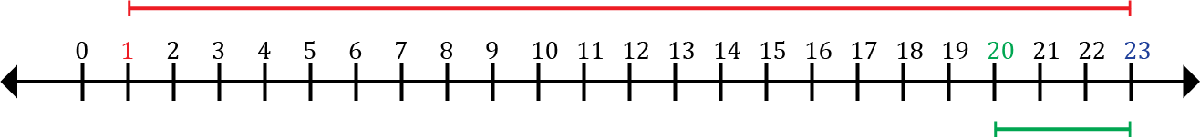                    

               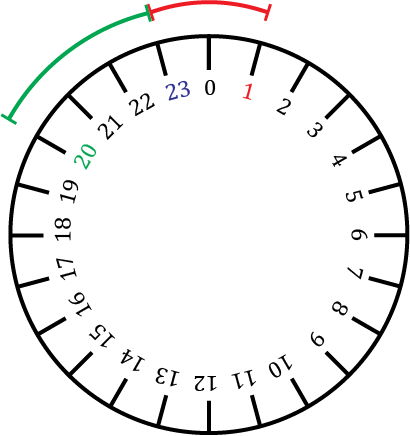

***Task: ****The code for transforming the hour number has been provided below. Perform a similar conversion for month number and day of week variables. Remember that there are 7 days in a week and 12 months in a year. Apply the appropriate scaling in each case.*

% Convert the hours to sin and cos features
nycHourly.HourX = sin(2*pi*nycHourly.Hour/24);
nycHourly.HourY = cos(2*pi*nycHourly.Hour/24);

% Convert the months to sin and cos features
nycHourly.MonthX = nycHourly.Month;
nycHourly.MonthY = nycHourly.Month;

% Convert the days of week to sin and cos features
nycHourly.DayOfWeekX =nycHourly.DayOfWeek;
nycHourly.DayOfWeekY = nycHourly.DayOfWeek;

 
 nycHourly

 % Delete the old features
nycHourly.Hour = [];
nycHourly.Month = [];
nycHourly.DayOfWeek = [];

After deleting the original hour, month, and day of week features, you have ten features extracted from the original time series. These can be used as inputs to train a machine learning model to predict the load for the next hour.

nycHourly

  ***Try***

- *Verify that the newly extracted date and time features are included in the table.*

- *Check one row of data to verify that the computed date and time features are correct. For example, at hour number 6, the value of *`HourX`* should be *`1`* and *`HourY`* should be *`0`*.*

### 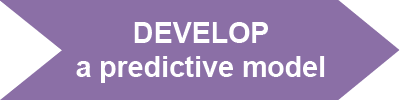

### 4.a. **Split into training and testing data**

Before training our machine learning models, split the available data into training and test subsets. Use the majority of the available data (May 8th, 2017 to Dec 31st, 2019) to train the predictive model and test it on a smaller set (Jan 1st to Dec 31st, 2020). 

***Task:**** Enter the correct years for the start and end dates of the ****training**** set.*

% Get the indices (row numbers) for training and test based on the range of the Date variable.
trainStart = "2010-May-08 00:00";
trainEnd = "2015-Dec-31 23:00";
idxtrain = isbetween(nycHourly.Date, datetime(trainStart,"TimeZone","America/New_York"), ...
                                     datetime(trainEnd,"TimeZone","America/New_York")); 
idxtest = nycHourly.Date > datetime(trainEnd,"TimeZone","America/New_York");
 

% Split the table into training and testing sets.
trainNYC = nycHourly(idxtrain,2:end)
testNYC = nycHourly(idxtest,2:end)

### 4.b. **Train a few machine learning models**

One of the most challenging parts of a machine learning workflow is to iterate over a few modeling techniques to identify what might work well for a particular dataset. The Statistics and Machine Learning Toolbox™ provides the [Regression Learner App](https://uk.mathworks.com/help/stats/regressionlearner-app.html) to try out multiple regression techniques and compare models.

***Task:**** Open the Regression Learner app from the ****Apps**** tab of the MATLAB toolstrip or by running this section. Then, follow the steps described below. *

regressionLearner
 

The app can take several minutes to open.

a) Start a **New Session**, open the drop-down list, and click **From Workspace**.

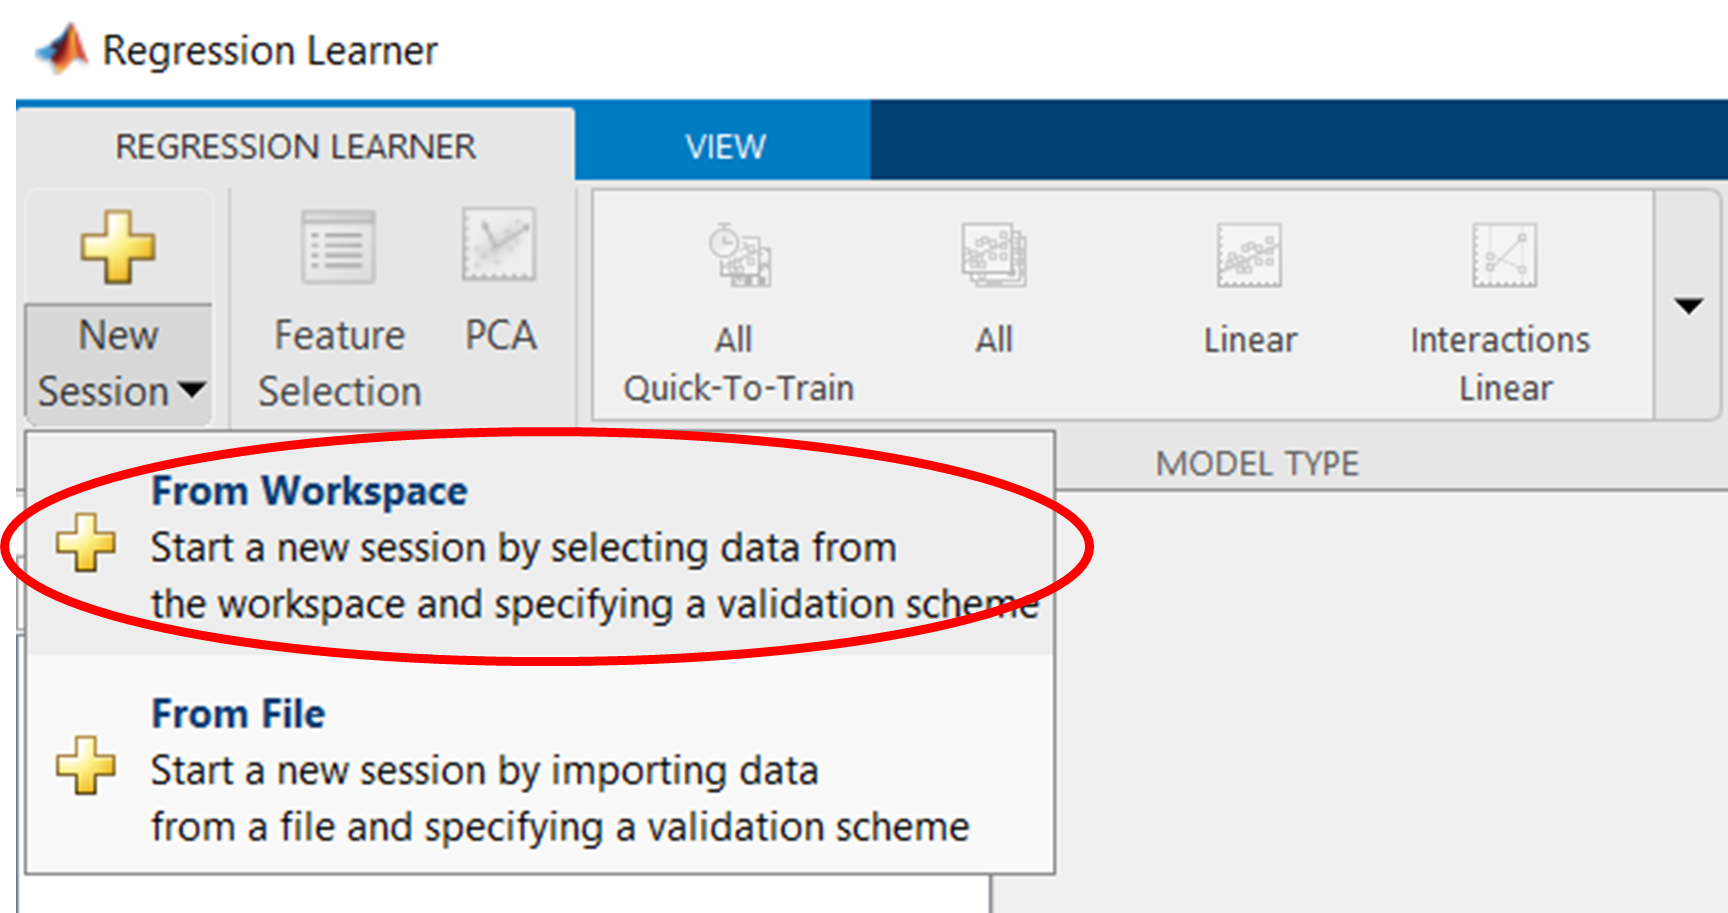

b) Choose the `trainNYC` variable and be sure to select the `Load` variable as the **Response **from the drop-down list. Then click **Start Session**.

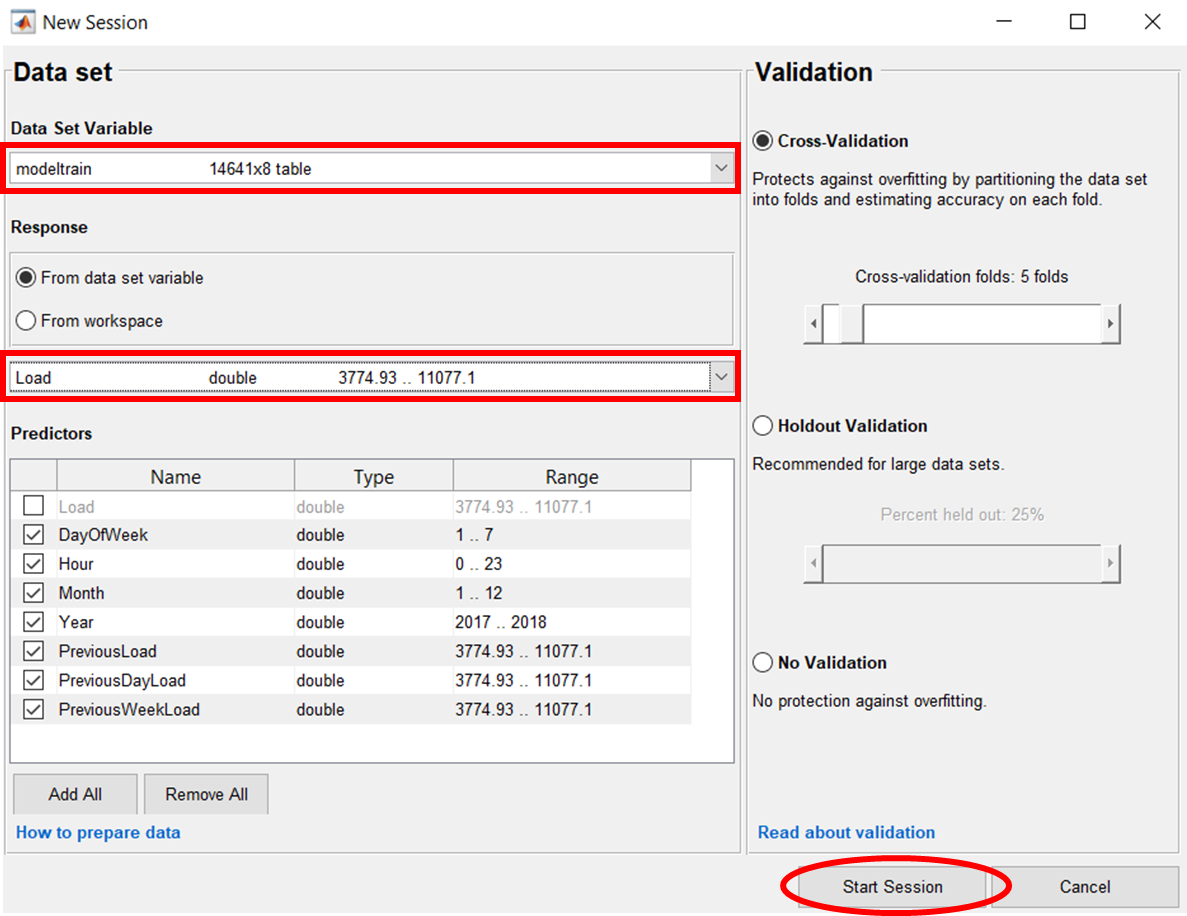

After importing the data you can train many different models. 

c) Use the drop-down in the **Model Type** section of the app toolstrip and select **All Quick-To-Train** models. Next, click **Train**.

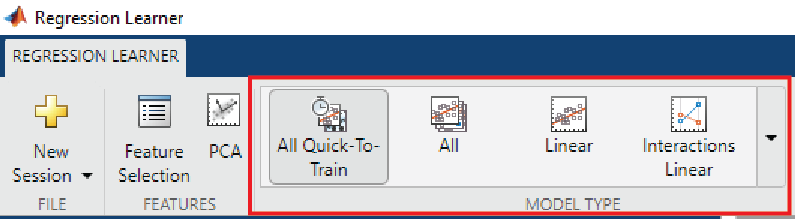

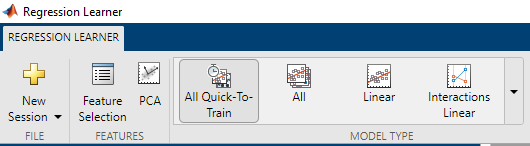d) Use the same drop-down to select a new model type. This time, select the **Bagged Trees **model. Click **Train**.

  ***Try***

- *Select a model in the ****Models**** pane (left) and see the different parameters in the ****Current Model**** pane.*

- *Select a model in the ****Models**** pane (left) and then observe the different types of plots. To generate the plots, select a type from the ****Plots**** section of the app toolsrip.*

                    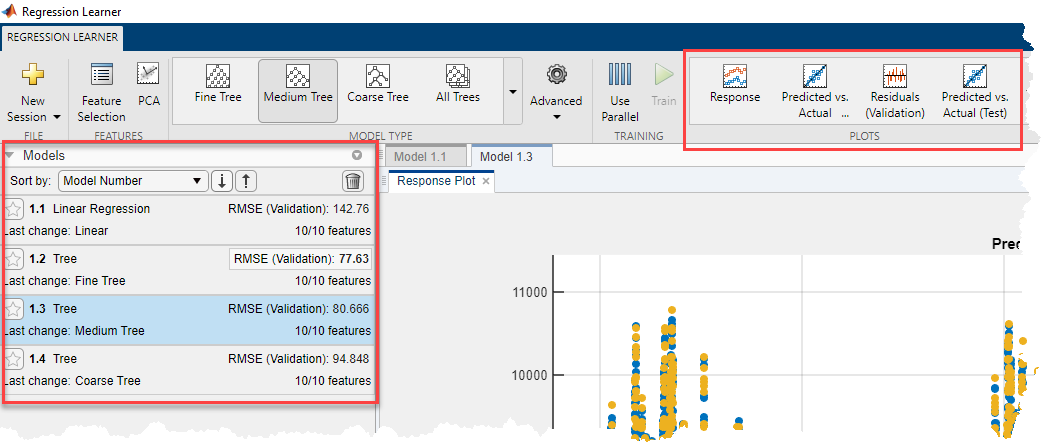

 **Reflect**

- What does an RMSE value represent? (**Hint**: Click **Training Results** in the **Current Model Summary** pane to learn more about the different metrics.) 

- Which model results in the lowest and the highest RMSE (validation)?

- Which model trains the fastest, and which one is the slowest to train?

### (Optional) Feature Selection

So far, you are using the ten features engineered by intuition. Often, not all features contribute to the learning of the model, and some might even confuse the model during the learning process. This results in a higher validation RMSE. Evaluating and choosing the most important features is called feature selection. By including only the relevant features, you can not only improve the performance of the model but also reduce the training time.

***Task: ***In the Regression Learner app, select the **Fine Tree** model. Click the **Feature Selection** button in the **Features** section of the app toolstrip. Select or deselect individual features one or more at a time. Train the model and observe the results for different combinations of features.

 **Reflect**

- Which feature combination resulted in the lowest and the highest RMSE (validation)?

- How many features are included in the best performance; that is, the lowest RMSE (validation)?

### **4.c. Save the trained model**

After deciding which of the models performs optimally, select the model in the **Model** pane on the left. Next, click the drop-down under **Export** and click **Export Model**. Name the model `trainedModel`.

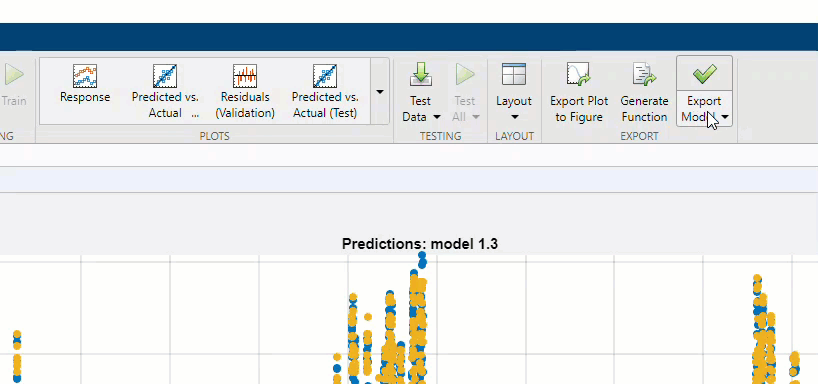

You can now minimize the Regression Learner app.

### 4.d. Apply and evaluate the model

#### **Predict future load**

You can now use the model to predict the future electricity load requirement. To test the model, use the `testNYC` dataset.

***Task:**** Click the ****How to predict**** button to view the data in the variable *`XTest`* and learn how to use the exported model to make predictions.*

XTest = testNYC(:,2:end)
trainedModel.HowToPredict
 

***Task:**** Replace the code in the edit field below to use *`predictFcn`* with the exported model (*`trainedModel`*) and get the predicted load for *`XTest`*. Click the *`Predict`* button to run the section.*

yTestPred = zeros(length(XTest))
 

#### **Evaluate the predictions**

Now that you have the measured load data for the test period, compare the predicted values to the actual ones by calculating the test RMSE. Plot the results. The app uses the RMSE metric for validating the models. Use the same measure to compute the error between the actual and the predicted loads for evaluating the model on the test data. 


$$\textrm{RMSE}=\sqrt{\frac{\sum_{i=1}^N {\left(x_i -\hat{x_i } \right)}^2 }{N}}$$
 

where $x_i$ is the actual time series data and $\hat{x_i }$ is the predicted time series data.

***Task:**** Run this section using the ****Show plot data**** button. Observe the variables in the displayed timetable. What values does *`plotTestData.Error`* contain?*

plotTestData = table2timetable(nycHourly(idxtest,:));
plotTestData.Pred = yTestPred;
plotTestData.Error = plotTestData.Pred - plotTestData.Load
 

***Task:**** Replace the code in the edit field below to compute the root mean-squared error (RMSE) using *`plotTestData.Error`*. Analyze the predicted and actual (observed) load outputs. (****Hint:**** Use the *`mean`* and *`sqrt`* functions. You can also look for *[*help*](https://www.mathworks.com/matlabcentral/answers/index)*).*

rmse = plotTestData.Error;
 

plotVars = {["Load" "Pred"], "Error"};
figure
stackedplot(plotTestData,plotVars, ...
    "Title", ["Comparison of actual and predicted load"; "Test RMSE= " + num2str(rmse)]);

  ***Try***

- *Open the graph in a separate window by clicking on the arrow in the top right corner.*

- *Zoom in and out by scrolling. Pan by clicking and dragging over the plot. To revert all changes and return to the original plot, use the home button * .

 **Reflect**

- Is there a pattern in the error? Where do the largest and smallest errors occur?

- Note the difference between the validation RMSE from the app and the test RMSE you calculated. Is it expected? Why?

- In addition to the historical electrical load data, what other external data will you consider incorporating in this model?

##  Practice Problem

How will you modify the script to forecast one day (24 hours) in advance instead of 1 hour?

- Switch the script to output inline mode with the **Output inline**    button on the **View** tab of the MATLAB toolstrip. All the code should be visible, along with the controls.

- Incorporate the changes required to train a model that is capable of predicting 24 hours in advance. (**Hint: **Inspect the lag features in 3.a., and identify the one that needs to be eliminated).

- Repeat the training and evaluation steps. How does your chosen final model compare to the previous one?

## 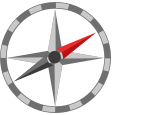 **Further Exploration**

- **Improve performance by further optimizing the model. ***Read the documentation page for the *[*Regression Learner app*](https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation-using-regression-learner-app.html)*. Experiment with feature selection, PCA, and other optimization options. *

- [**Develop a model programmatically**](matlab:open('./FE1_programmaticML.mlx'))**.**

- [**Use deep learning to perform time series forecasting**](matlab:open('./FE2_loadForecastDL.mlx'))**.**